# Zadanie domowe

## 1. Definicja

syms f(x) a b
f(x) = 2*cos(x)

$$f(x) = 2\,\cos\left(x\right)$$

a = - pi/4

a = -0.7854

b = pi/3

b = 1.0472

calkerman = int(f(x), [a b], 'Hold', true)

$$calkerman = \int_{-\frac{\pi }{4}}^{\frac{\pi }{3}}2\,\cos\left(x\right)\mathrm{d}x$$

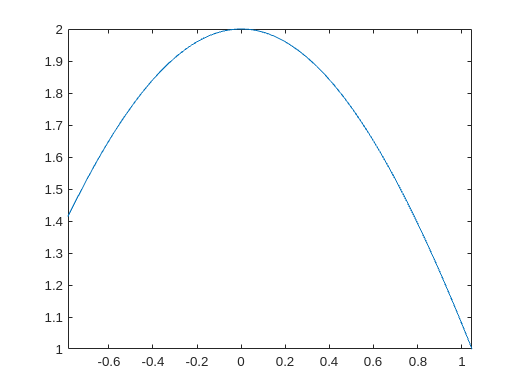

wynik = release(calkerman);
fplot(f(x),[a, b])

## metoda trapezów

n = 10;
h = (b-a)/n;
przedzial = a:h:b;
for i = 1:n+1
    Ygreki(i) = f(przedzial(i));
end

wynik_trapez = -f(a)/2 -f(b)/2;
for i = 1:n+1
    wynik_trapez = wynik_trapez + Ygreki(i);
end

wynik_trapez = wynik_trapez * h;

## rukowanie na wykresie

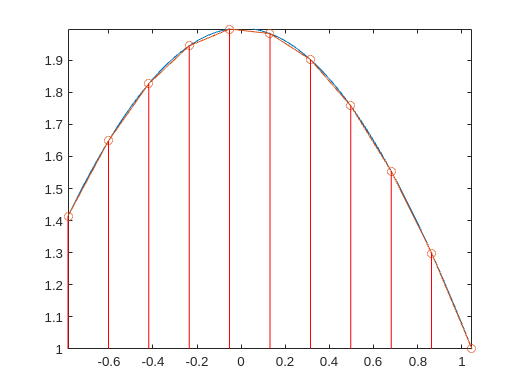

% Zgodnie z poleceniem zadania, poniższa linijka działa poprawnie, jednak
% matlab 2024.a zgłasza ostrzeżenie.
%ezplot(f); % EZPLOT is not recommented. Use FPLOT or ...
fplot(f)

hold on;
plot(przedzial,Ygreki, 'o-');
axis([a,b,double(min(Ygreki)), double(max(Ygreki))])
for i = 1:n+1
    plot([przedzial(i), przedzial(i)], [0, Ygreki(i)], 'r')
end
hold off

## Wyniki obliczeń

wynik

$$wynik = \sqrt{2}+\sqrt{3}$$

wynik_trapez

$$wynik\_trapez = \frac{7\,\pi \,\left(2\,\cos\left(\frac{2\,\pi }{15}\right)+2\,\cos\left(\frac{\pi }{24}\right)+2\,\cos\left(\frac{3\,\pi }{40}\right)+2\,\cos\left(\frac{11\,\pi }{40}\right)+2\,\cos\left(\frac{\pi }{60}\right)+2\,\cos\left(\frac{13\,\pi }{60}\right)+2\,\cos\left(\frac{19\,\pi }{120}\right)+2\,\cos\left(\frac{23\,\pi }{120}\right)+\frac{\sqrt{2}}{2}+\frac{\sqrt{2}\,\sqrt{\sqrt{5}+5}}{2}+\frac{1}{2}\right)}{120}$$

wynik_liczbowo = double(wynik)

wynik_liczbowo = 3.1463

wynik_trapez_liczbowo = double(wynik_trapez)

wynik_trapez_liczbowo = 3.1375

sigma = abs(double(wynik)-double(wynik_trapez))

sigma = 0.0088